# **Experimental Modal Analysis(EMA):**     A **SIMO** Cantilever Vibration Experiment

In the following script we'll analyze some time series data collected from a **SIMO** Vibration experiment conducted on a Cantilever. 

## **Objective:**

- Convert the simulation times series measurements into **Frequency Response Functions** **(FRFs)**

- Extract the **Modal properties** ($\omega_n \;,\zeta_n$) from the **FRFs**.

- Extract the **MODE SHAPEs** at our measurement locations

We'll use MATLAB's functions:

- [`modalfrf()`](matlab:  doc modalfrf)` , `[`modalsd()`](matlab:  doc  modalsd)` , `[`modalfit()`](matlab:  doc  modalfit) 

## **Background:   Part_1 - The parametric FRF equation for a Mechanical system**

Recall the parametric equation of a Frequency Response Function (FRF) of a Mechanical structure:

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\frac{R_k }{s-\lambda_k }\;\;+\;\;\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;e\;\;+\;\;\;\;\frac{f}{s^2 }\right.$$
          

where we have:

- **MODAL poles**:       $\lambda_k \;\;\;=\;-\zeta_k \ldotp \omega_{n_k } \;\;\;+\;\;\;j\ldotp \omega_{n_k } \ldotp \sqrt{\;1\;-{\zeta_k }^2 \;}$

- **RESIDUES**:            $R_k$

## **Background:   Part_2 - The Modal properties extraction process**

Our **Modal Fitting** process can be summarized by the following workflow pipeline:

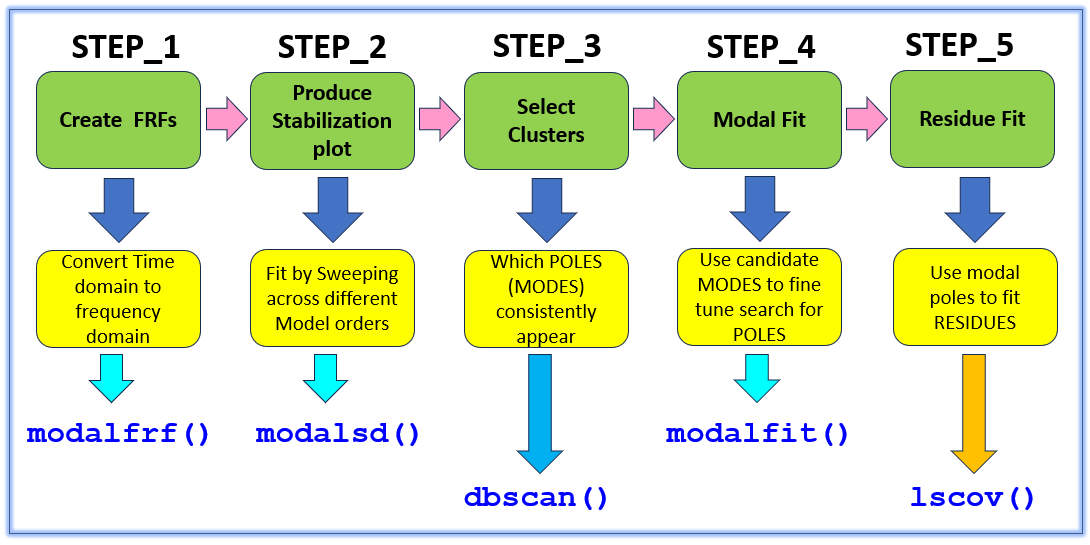

## **Background:   Part_3 - Where did our time series data come from**

- The DATA:

- The timeseries data that we'll be analyzing is stored in the EXCEL file `MEAS_CANTIL_01_shaker_T_F_v2_to_v21.xls`

- The MODEL:

- The timeseries data analyzed in this script was generated by a 20-element **Finite Element model** of a cantilever.  This** simulated time series data** was created by the file [`APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx`](matlab:  open  APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx)

- The EXCITATION:

- The excitation Force applied to the cantilever was a **Band Limited Random Noise force** applied via a **SHAKER**.

- The shaker force was applied at **Node 6** of the cantilever and was applied in the **vertical (Y-axis) direction**

- The RESPONSE:

- We measured the **transverse** **displacements** at **20** locations along the cantilever, i.e.:  $\left\lbrace v_2 \;\;,\;v_3 \;\;,v_4 \;\;,v_5 \;\;,\;\ldotp \ldotp \ldotp ,\;v_{19} \;\;,v_{20} \;\;,\;v_{21} \right\rbrace$

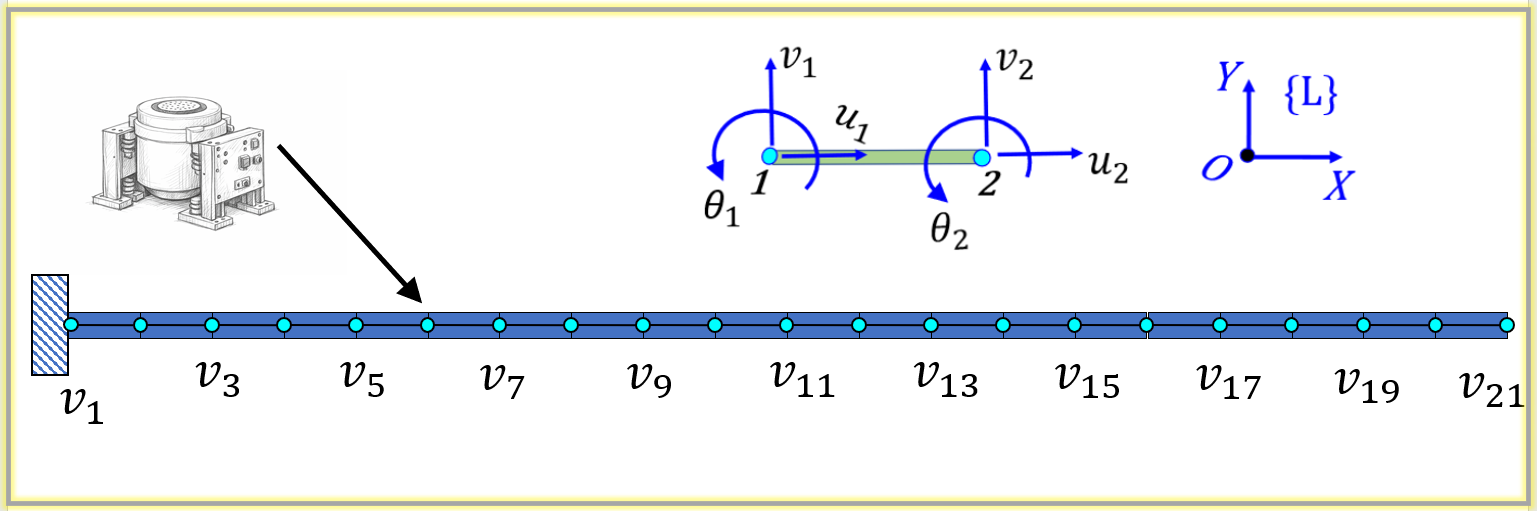

## **Analytic Modal frequencies and Mode shapes:**

For the cantilever presented in [`APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx`](matlab:  open  APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx)`, `the first 4 analytic natural frequencies of ***bending*** vibration computed using **Engineering Beam Theory,**  are listed in column_A of **Table(1) below**.  Column_B of Table(1) summarizes the modes computed from the 20 element **FE model** of the cantilever (i.e.: a  60-dof model representing transverse and axial dynamics). Note that the first 4-modes predicted by the FE model are within 0.01 Hz of the analytic beam theory modes. For calculation details see:

- [`APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx`](matlab:  open  APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx)

- [`bh_cantil_analytic_modes()`](matlab:  open  bh_cantil_analytic_modes)

**Table(1): **  Analytic Bending modes and Mode shapes.  AND FE model modes. 

`Bradley Horton:  bhorton@mathworks.com`

## RESOURCES:

The following Appendix files are useful for some background knowledge:

- [`APPENDIX_00_Matrix_Algebra_Essentials_for_Modal.mlx`](matlab:  open bh_Modal.APPENDIX_00_Matrix_Algebra_Essentials_for_Modal)  

- [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

- [`APPENDIX_02_Complex_Residue_Curve_Fit.mlx`](matlab:  open  bh_Modal.APPENDIX_02_Complex_Residue_Curve_Fit)    

- [`APPENDIX_03_Signal_things.mlx `](matlab:  open  bh_Modal.APPENDIX_03_Signal_things)           

- [`APPENDIX_04_tf_and_frf.mlx`](matlab:  open bh_Modal.APPENDIX_04_tf_and_frf)

- [`APPENDIX_05_irf_and_fft_and_frf.mlx`](matlab:  open bh_Modal.APPENDIX_05_irf_and_fft_and_frf)

- [`APPENDIX_06_PHASE_PLOTS.mlx`](matlab:  open bh_Modal.APPENDIX_06_PHASE_PLOTS)

- [`APPENDIX_07_NATURAL_DAMPED_and_RESONANT.mlx`](matlab:  open bh_Modal.APPENDIX_07_NATURAL_DAMPED_and_RESONANT)

- [`APPENDIX_08_explore_pulse.mlx`](matlab:  open bh_Modal.APPENDIX_08_explore_pulse)

## Some Heads up comments before you start:

-  the script takes about 30 seconds to run on Brad's laptop

- I've noticed that sometimes the script "freezes" during the last set of plots - which is annoying.  A temporary fix is to Right click in the output panel and select **"Clear All Output"** before running the script.

# Load in the FULL Time Series measurement data set

Clear your workspace

clear

Recall that our time series data was generated in the script [`APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx`](matlab:  open APPENDIX_A_SIMO_CANTILEVER_create_dataset)

MEAS_tseries_tab = readtable("MEAS_CANTIL_01_shaker_T_F_v2_to_v21.xlsx");

Have a peak at the FULL measurement data set

% head(MEAS_tseries_tab)

## Reduce the number of Response Channels

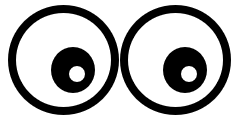 To reduce the computational time involved in this analysis, let's only consider every 2nd ***response*** measurement channel

MEAS_tseries_tab = MEAS_tseries_tab(:, [1,2, 3:2:end]);
vdof_labels_list = MEAS_tseries_tab.Properties.VariableNames(3:end);
vdof_labels_list = string(vdof_labels_list)

Have a peak at the measurement data that we've retained

whos MEAS_tseries_tab

head(MEAS_tseries_tab)

## Set up some Signal processing parameters:

Fs_hz      = 1/(MEAS_tseries_tab.t(2) - MEAS_tseries_tab.t(1))
tmp_win_N  = floor( height(MEAS_tseries_tab) / 5 );  % 4
THE_WINDOW = hann(tmp_win_N);
n_OVERLAP  = 0; %floor(tmp_win_N/2);

Pull out the input(FORCE) and response(DISPLACEMENTS) data

in_col    = MEAS_tseries_tab.F;
out_mat   = MEAS_tseries_tab{:, 3:end};

whos in_col  out_mat

# **Step_1:**   Estimate the System **FRF** from our timeseries Measurements:

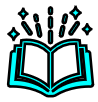 **DOC**:   see [`modalfrf()`](matlab:  doc modalfrf)

[all_frf, all_f, tmp_coh] = modalfrf(in_col, out_mat, Fs_hz, THE_WINDOW, n_OVERLAP, Sensor="dis");

whos  all_frf  all_f

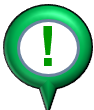 **NOTE:**  the frequency vector `all_f` (in Hz) that is returned only includes frequencies up to the NYQUIST frequency

all_f(end)

## Visualize the MEASURED (estimated) FRFs

**Define some data containers for storing these estimated FRFs:**

meas.frf       = all_frf;
meas.coh       = tmp_coh;   % understood will be NaN IFFF only 1 window block used
meas.f_hz      = all_f; 
meas.w         = 2*pi*meas.f_hz;
meas.frf_dB    = 20*log10(abs(meas.frf));
meas.phase_deg = rad2deg(  angle(meas.frf)   );

#### Specify the Frequency range of interest

Let's also select a frequency range of interest that we'll focus on when we eventually do the fitting task(later in this script)

roi.range_Hz = [0, 150];

tmp_ind      = find( (meas.f_hz > roi.range_Hz(1)) & (meas.f_hz < roi.range_Hz(2))  );

roi.f_Hz     = meas.f_hz(tmp_ind);
roi.frf      = meas.frf(tmp_ind, :);
roi.frf_all  = all_frf(tmp_ind,  :);
roi.coh      = meas.coh(tmp_ind, :);

#### And plot the Measured (estimated) FRFs

Plot ***every 2nd one*** to reduce the number of generated plots

for kk=1:2:width(meas.frf)

    figure;
          hax(1) = subplot(2,1,1); 
           yyaxis left
               plot(roi.f_Hz, 20*log10( abs(roi.frf(:,kk))), "-b.", "DisplayName","MEAS")
                   grid on; axis tight
                   xlabel("(Hz)");   ylabel("(dB)");
           yyaxis right
               plot(roi.f_Hz, roi.coh(:,kk), "-m.", "DisplayName","COH")
                   grid on; axis tight
                   xlabel("(Hz)");   ylabel("(Coherance)");

                   title("Measured FRF for RESPONSE channel ---> ("+vdof_labels_list(kk)+")", "FontName","Courier", "Interpreter","none")
                   %title("Measured FRF for RESPONSE channel $\Longrightarrow("+vdof_labels_list(kk)+")$", "FontName","Courier", "Interpreter","latex")
          hax(2) = subplot(2,1,2); 
               plot(roi.f_Hz, rad2deg( angle(roi.frf(:,kk)) ), "-b.")
                   grid on; axis tight
                   xlabel("(Hz)");  ylabel("(degrees)")

end

# **STEP_2:**    Produce Stabilization plot

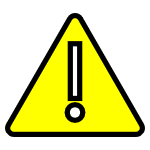 **NOTE:  **for this Cantilever data set (SIMO) .. the LSRF method is tooooo slow ...So I recommend you do NOT select that

try_it_FitMethod = "lsce";

### Consider the Stabilization diagram

 **DOC**:   see  [`modalsd()`](matlab:  doc  modalsd)

We'll use ALL of our FRF channels

MAXMODES = 30;

figure   %  the STABILIZATION plot
    fn_sd = modalsd( all_frf, meas.f_hz, Fs_hz, ...
                     MaxModes=MAXMODES, ...
                     FreqRange=roi.range_Hz, ...
                     FitMethod=try_it_FitMethod)

Maybe we weren't able to sweep across the desired MAX modes

ACTUAL_MAXMODES = size(fn_sd, 2);      

Remove NaNs and ZEROS

FN_HZ_ALL          =   rmmissing(fn_sd(:));
tmp_ind            =  FN_HZ_ALL == 0;
FN_HZ_ALL(tmp_ind) = [];

# **STEP_3:**   Look for Clusters from the Stabilization plot

 REMEMBER: many of the modes will NOT be real modes, rather they will be computational ones that we need to ignore. 

### Select modes based on CLUSTERING and a count threshold

 So let's utilize a data **CLUSTERING** algorithm to semi automate where we think the real modes are.  We will need to tune this, e.g.:  

- the **neighborhood radius** may need some "trial/error" tuning.

- the **minimum number of counts** within a cluster may need some "trial/error" tuning.

See:  [`bh_collect_by_clustering()`](matlab:  open bh_collect_by_clustering)

clust_fHz_radius = 1;
clust_min_counts = floor(0.66*ACTUAL_MAXMODES);
clust_fHz_range  = roi.range_Hz;

my_fhz_list_FROM_CLUST = bh_collect_by_clustering(FN_HZ_ALL, clust_fHz_radius, clust_min_counts, fHz_range=clust_fHz_range);

So our candidate resonant frequencies are:

my_fhz_list_FROM_CLUST

So from the stabilization diagram, how many modes do you think we should try and fit ?

-  **NOTE:** We'll also specify a HIGHER target number of modes to fit ... to see if there's anything else there. Overspecifying the number of modes gives better (?) results.

NUM_MODES_TO_FIT = 10    

# **STEP_4:**   Extract our Modal Poles

- see DOC for [`modalfit()`](matlab:  doc  modalfit) 

- **NOTE: ** We'll specify the frequencies extracted from our histogram and pass these into [`modalfit()`](matlab:  doc  modalfit) as 'PhysFreq'.  

[fn,dr,ms] = modalfit( all_frf, meas.f_hz, Fs_hz, ...
                       NUM_MODES_TO_FIT, ...
                       PhysFreq=my_fhz_list_FROM_CLUST, ...
                       FreqRange=roi.range_Hz, ...
                       FitMethod=try_it_FitMethod);

Remove any Nans:

tmp_ind  = ~isnan(fn) & ~isnan(dr);

fn_clean = fn(tmp_ind);
dr_clean = dr(tmp_ind);

Tabulate these

array2table([fn(:), dr(:)],'VariableNames',{'fn_hz','zeta'})

# **STEP_5:**   Extract our Modal RESIDUES

For each FRF

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\;\;\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;\;\;\;\frac{f}{s^2 }\;\;\;+\;\;\;\;\;\;e\right.$$


Compute the residues for each mode in each FRF

- `size(my_R_mat) == NUM_MODES x NUM_RESP_CHANNELS`

my_R_mat = NaN( length(fn_clean),  size(all_frf, 2) );

for kk=1:size(my_R_mat,2)
 
    [my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( fn_clean, ...
                                                        dr_clean, ...
                                                        roi.f_Hz, ...
                                                        roi.frf_all(:,kk)    );
    my_R_mat(:,kk) = my_R(:);
end

#### Visual inspection of Residues

Visually confirm **Residues** have phases close to either 90 degrees OR -90 degrees

- For rationale, see:  [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

tmp_res_phas_degs = abs( rad2deg(angle(my_R_mat)) );

figure;
    heatmap( tmp_res_phas_degs, "Colormap", jet(20), ...
             YDisplayLabels="MODE_"+(1:height(my_R_mat)), ...
             XDisplayLabels=vdof_labels_list, ...
             Interpreter="none");
        title("ABS value of Residue PHASE (degrees)")
         clim([80 100])

#### Summarize the Identified MODAL properties

fprintf("\n FINAL results ----> ")
RESULTS_tab = array2table([fn_clean(:), dr_clean(:), (2*pi*fn_clean(:))],...
                            'VariableNames',{'fn_Hz','zeta', 'wn_radpersec'});
RESULTS_tab

# Extract Mode shapes and plot them

Assume Proportional damping and convert the Residues into normal mode data

- For rationale, see:  [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

md_shapes = imag(my_R_mat);

#### Plot the mode shapes

Recall the format of our RESIDUE matrix

- `size(my_R_mat) == NUM_MODES x NUM_RESP_CHANNELS`

 So ? - So a ***row*** of the `my_R_mat `matrix corresponds to a mode SHAPE vector

figure;
  for kk=1:size(md_shapes,1)
    % extract mode KK
    plot(md_shapes(kk,:), "-o", "DisplayName","MODE "+kk);
    hold on
  end
  grid("on")
  xlabel("NODE ID")
  legend('Location','best')
  %drawnow 

# Compare ALL Measurement FRFs against the fitted models

OK - so what do our **fitted** FRFs look like when compared against the **Measured** FRFs ?

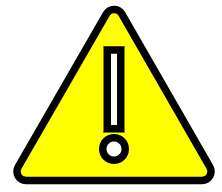 **NOTE:**  I've noticed that sometimes the script "freezes" during the last set of plots - which is annoying. IFFF you observe this ... just reduce the number of FRFs to plot below.

fprintf("\n .... PLOT fitted and measured FRFs");
  
NUM_FRFs =  size(roi.frf_all, 2);

for kk=1:2:NUM_FRFs

    fprintf("\n .... starting [%2d] of %2d", kk, NUM_FRFs);

    [my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( RESULTS_tab.fn_Hz, ...
                                                        RESULTS_tab.zeta, ...
                                                        roi.f_Hz, ...
                                                        roi.frf_all(:,kk) );

   my_sdyn_OBJ = bh_Modal.CLS_sdyn_frf( RESULTS_tab.zeta, ...
                                        2*pi*RESULTS_tab.fn_Hz, ...
                                        my_R, my_e, my_f);

   my_sdyn_OBJ.s_w_fhz_col = roi.f_Hz;

    figure;
      hax(1) = subplot(2,1,1); 
           plot(roi.f_Hz, 20*log10( abs(roi.frf_all(:,kk))), "-r.", "DisplayName","MEAS")
               grid on; axis tight
               xlabel("(Hz)");   ylabel("(dB)");
               title("FRF ---> ("+vdof_labels_list(kk)+")", "Interpreter","none")
               %title("$FRF \Longrightarrow ("+vdof_labels_list(kk)+")$", "Interpreter","latex")
      hax(2) = subplot(2,1,2); 
           plot(roi.f_Hz, rad2deg( angle(roi.frf_all(:,kk)) ), "-r.")
               grid on; axis tight
               xlabel("(Hz)");  ylabel("(degrees)")

    hold(hax(1),"on")
        axes(hax(1))
        plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.db, "-b","DisplayName","fit");

    hold(hax(2))
        axes(hax(2))
        plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.phase("DEGS"), "-b");

    legend(hax(1), "Location", "best")

    linkaxes(hax, "x")  

    drawnow

end

# View FRF and TF in 3D

Select an FRF to view in 3D

DESIRED_SENSOR_LABEL = vdof_labels_list(1);
THE_IND = find(vdof_labels_list == DESIRED_SENSOR_LABEL);

Create the fitted FRF

[my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( RESULTS_tab.fn_Hz, ...
                                                    RESULTS_tab.zeta, ...
                                                    roi.f_Hz, ...
                                                    roi.frf_all(:,THE_IND) );

my_sdyn_OBJ = bh_Modal.CLS_sdyn_frf(        RESULTS_tab.zeta, ...
                                       2*pi*RESULTS_tab.fn_Hz, ...
                                       my_R, my_e, my_f);

my_sdyn_OBJ.s_w_fhz_col = roi.f_Hz;

View it in 3D

my_sdyn_OBJ.plot_3d_db()
    title("FRF for ---> ("+DESIRED_SENSOR_LABEL+")", Interpreter="none", FontName="Courier New");